# Repeat Reunion Part 3.B: Session Variance Inferred from Supervised Learning Algorithm

## Set up variables 

For the dyad analysis

    
colorcodes_f = [.75 0 0 ; .4 0 0 ; 1 .35 .35];
colorcodes_m = [0 0 .75 ; 0 0 .4 ; .35 .35 1];

  labels_pair = rdb_rr.paircode;
  exp_pair = rdb_rr.exposurenum;
  
  indfemOneFive_f = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum < 2), fem_ind);
  indfemOneFive_cag_f = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum == 0), fem_ind);
  indfemOneFive_str_f = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum == 1), fem_ind);
  
  indmalOneFive_m = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum < 2), mal_ind);
  indmalOneFive_cag_m = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum == 0), mal_ind);
  indmalOneFive_str_m = intersect(find(rdb_rr.exposurenum' < 6 & rdb_rr.strangernum == 1), mal_ind);
  
  u_p1_f = unique(labels_pair(indfemOneFive_cag_f));
  u_p2_f = unique(labels_pair(indfemOneFive_str_f));
  u_p_f = [u_p1_f ; u_p2_f];
  
  lp_f = length(u_p1_f);
  
  u_p1_m = unique(labels_pair(indmalOneFive_cag_m));
  u_p2_m = unique(labels_pair(indmalOneFive_str_m));
  u_p_m = [u_p1_m ; u_p2_m];
  
  lp_m = length(u_p1_m);
  


## Pairwise SVM (Dyad classification success)

Here I am going to create an SVM model to assess  between pairs of dyads.

We will look at between-cagemates, between-strangers, and cagemate-strangers.

SVM

female

 %  sbID = sumbehavID2.^(1/3);
%    labels_pair = rdb_rr.paircode;
%   exp_pair = rdb_rr.exposurenum;
%   [ClassDistLIN, CDbyday] = IVclass_sess2(sbID, indfemOneFive, u_p_f, labels_pair, 'linear', exp_pair);
   
% ClassDistRBF = IVclass_sess(sbID, indfemOneFive, u_p, labels_pair, 'rbf'); 
%ClassDistLIN = IVclass_sess(sbID, indfemOneFive, u_p, labels_pair, 'linear');

load ClassDistLIN_210715
ClassDistLIN_f = ClassDistLIN; 
CDbyday_f = CDbyday;

male

%   [ClassDistLIN, CDbyday] = IVclass_sess2(sbID, indmalOneFive_m, u_p_m, labels_pair, 'linear', exp_pair);
   
%ClassDistRBF = IVclass_sess(sbID, indfemOneFive, u_p, labels_pair, 'rbf'); 
%ClassDistLIN = IVclass_sess(sbID, indfemOneFive, u_p, labels_pair, 'linear');
%load ClassDistLIN_210715

%ClassDistLIN_m = ClassDistLIN; 
%CDbyday_m = CDbyday;

load ClassDistLIN_220722.mat

%%save time--load saved variables instead of making new ones:
%%
%load ClassDiscriminationMatrices_210615 
%%
%%variables names:
%%ClassDistRBF ClassDistLIN

%ClassDistRBF(find(eye(length(ClassDistRBF)))) = nan;
ClassDistLIN_f(find(eye(length(ClassDistLIN_f)))) = nan;
for i = 1:5
    CDbyday_f(find(eye(length(ClassDistLIN_f))),i) = nan;
end

ClassDistLIN_m(find(eye(length(ClassDistLIN_m)))) = nan;
for i = 1:5
    CDbyday_m(find(eye(length(ClassDistLIN_m))),i) = nan;
end

  

### Plot the SVM data

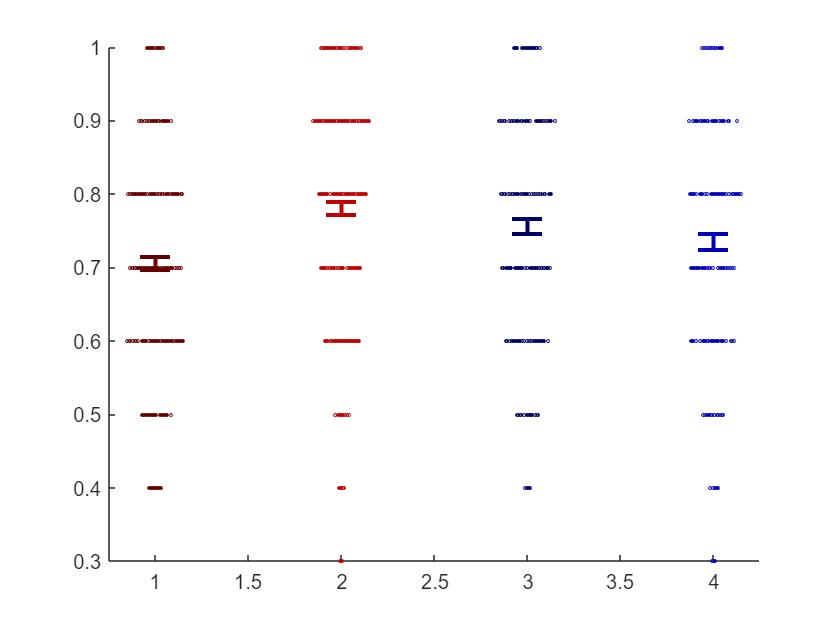

  lp_f = length(u_p1_f);
  figure
  hold on

%   cg_rbf = reshape(ClassDistRBF(1:lp,1:lp), 1, []);
%   cg_rbf = cg_rbf(~isnan(cg_rbf));
%   st_rbf = reshape(ClassDistRBF(lp+1:2*lp, lp+1:2*lp), 1, []);
%   st_rbf = st_rbf(~isnan(st_rbf));
  
  cg_lin_f = reshape(ClassDistLIN_f(1:lp_f,1:lp_f), 1, []);
  cg_lin_f = cg_lin_f(~isnan(cg_lin_f));
  st_lin_f = reshape(ClassDistLIN_f(lp_f+1:2*lp_f, lp_f+1:2*lp_f), 1, []);
  st_lin_f = st_lin_f(~isnan(st_lin_f));
  
  cg_lin_m = reshape(ClassDistLIN_m(1:lp_m,1:lp_m), 1, []);
  cg_lin_m = cg_lin_m(~isnan(cg_lin_m));
  st_lin_m = reshape(ClassDistLIN_m(lp_m+1:2*lp_m, lp_m+1:2*lp_m), 1, []);
  st_lin_m = st_lin_m(~isnan(st_lin_m));
  
  
  

clear s
  s{1} = swarmchart(ones(length(cg_lin_f),1), cg_lin_f , 2, 'MarkerEdgeColor', colorcodes_f(2,:));
  s{2} = swarmchart(2*ones(length(st_lin_f),1), st_lin_f, 2, 'MarkerEdgeColor', colorcodes_f(1,:));

  s{3} = swarmchart(3*ones(length(cg_lin_m),1), cg_lin_m , 2, 'MarkerEdgeColor', colorcodes_m(2,:));
  s{4} = swarmchart(4*ones(length(st_lin_m),1), st_lin_m, 2, 'MarkerEdgeColor', colorcodes_m(1,:));
  
  
%  s{3} = swarmchart(3*ones(length(cg_rbf),1), cg_rbf, 2, 'b') ;
%  s{4} = swarmchart(4*ones(length(st_rbf),1), st_rbf, 2, 'r');
 
 for i = 1:4
     set(s{i}, 'XJitterWidth', .3);
 end
  box off
    lp_f = length(u_p1_f);
    lp_m = length(u_p1_m);

    %  figure
%  hold on
%  e1 = errorbar([1 3], [nanmean(cg_lin) nanmean(cg_rbf)], ...
%      [nanstd(cg_lin) nanstd(cg_rbf)]/sqrt(length(cg_lin)-1), 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 2, 'CapSize', 15);
%  e1 = errorbar([2 4], [nanmean(st_lin) nanmean(st_rbf)], ...
%      [ nanstd(st_lin) nanstd(st_rbf)]/sqrt(length(cg_rbf)-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 2, 'CapSize', 15);
 e1 = errorbar(1, nanmean(cg_lin_f), ...
     nanstd(cg_lin_f)/sqrt(length(cg_lin_f)-1), 'LineStyle', 'none', 'Color', colorcodes_f(2,:), 'LineWidth', 2, 'CapSize', 15);
 e1 = errorbar(2, nanmean(st_lin_f), ...
     nanstd(st_lin_f)/sqrt(length(st_lin_f)-1), 'LineStyle', 'none', 'Color', colorcodes_f(1,:), 'LineWidth', 2, 'CapSize', 15);

 e1 = errorbar(3, nanmean(cg_lin_m), ...
     nanstd(cg_lin_m)/sqrt(length(cg_lin_m)-1), 'LineStyle', 'none', 'Color', colorcodes_m(2,:), 'LineWidth', 2, 'CapSize', 15);
 e1 = errorbar(4, nanmean(st_lin_m), ...
     nanstd(st_lin_m)/sqrt(length(st_lin_m)-1), 'LineStyle', 'none', 'Color', colorcodes_m(1,:), 'LineWidth', 2, 'CapSize', 15);


 box off
  set(get(e1, 'parent'), 'XLim', [.75 4.25]); 


%  X1 = female/male
%  X2 = 
  

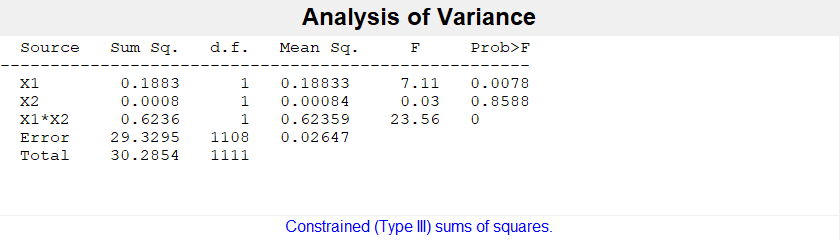

anovacell = cell(3,1);
anovacell{1} = [cg_lin_f' ; st_lin_f' ; cg_lin_m' ; st_lin_m'];
anovacell{2} = [ones(length(cg_lin_f),1) ; 2*ones(length(st_lin_f),1) ; ones(length(cg_lin_m),1) ; 2*ones(length(st_lin_m),1)];
anovacell{3} = [ones(length(cg_lin_f),1) ; ones(length(st_lin_f),1) ; 2*ones(length(cg_lin_m),1) ; 2*ones(length(st_lin_m),1)];

[P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');

  
  %  [a b] = ranksum(cg_lin, st_lin)
%  [a, b, n, stats] = ttest2(cg_lin, st_lin)

### Classification success by day

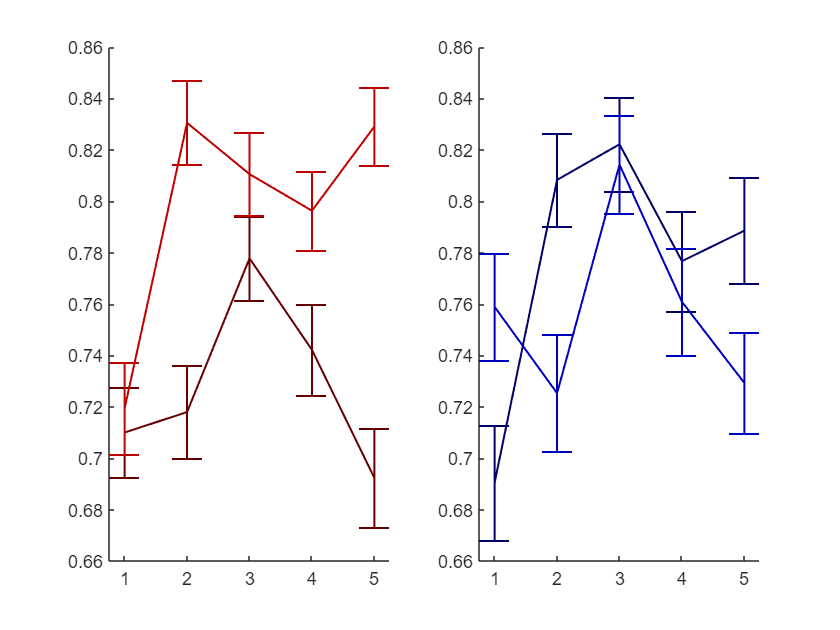

  


figure
  hold on

  for i = 1:5
  cg_linD_f{i} = reshape(CDbyday_f(1:lp_f,1:lp_f, i), 1, []);
  cg_linD_f{i} = cg_linD_f{i}(~isnan(cg_linD_f{i}));
  st_linD_f{i} = reshape(CDbyday_f(lp_f+1:2*lp_f, lp_f+1:2*lp_f, i), 1, []);
  st_linD_f{i} = st_linD_f{i}(~isnan(st_linD_f{i}));
  
  cg_linD_m{i} = reshape(CDbyday_m(1:lp_m,1:lp_m, i), 1, []);
  cg_linD_m{i} = cg_linD_m{i}(~isnan(cg_linD_m{i}));
  st_linD_m{i} = reshape(CDbyday_m(lp_m+1:2*lp_m, lp_m+1:2*lp_m, i), 1, []);
  st_linD_m{i} = st_linD_m{i}(~isnan(st_linD_m{i}));
  
  
 
  clear s

%  s{1} = swarmchart(ones(length(cg_lin),1), cg_lin , 2, 'b');
%  
%  s{2} = swarmchart(2*ones(length(st_lin),1), st_lin, 2,'r');
 
% s{3} = swarmchart(3*ones(length(cg_rbf),1), cg_rbf, 2, 'b') ;
% s{4} = swarmchart(4*ones(length(st_rbf),1), st_rbf, 2, 'r');
 
%  for j = 1:2
%      set(s{j}, 'XJitterWidth', .3);
%  end
  box off
    lp_f = length(u_p1_f);
%  figure
%  hold on
%  e1 = errorbar([1 3], [nanmean(cg_lin) nanmean(cg_rbf)], ...
%      [nanstd(cg_lin) nanstd(cg_rbf)]/sqrt(length(cg_lin)-1), 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 2, 'CapSize', 15);
%  e1 = errorbar([2 4], [nanmean(st_lin) nanmean(st_rbf)], ...
%      [ nanstd(st_lin) nanstd(st_rbf)]/sqrt(length(cg_rbf)-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 2, 'CapSize', 15);

%    [a(i), b(i), s] = ranksum(cg_linD{i}, st_linD{i})
  end
  
  subplot(1,2,1)
  hold on
   e1 = errorbar([1:5], [nanmean(cg_linD_f{1}) nanmean(cg_linD_f{2}) nanmean(cg_linD_f{3}) nanmean(cg_linD_f{4}) nanmean(cg_linD_f{5})], ...
     [nanstd(cg_linD_f{1}) nanstd(cg_linD_f{2}) nanstd(cg_linD_f{3}) nanstd(cg_linD_f{4}) nanstd(cg_linD_f{5})]./...
     [sqrt(length(cg_linD_f{1})-1) sqrt(length(cg_linD_f{2})-1) sqrt(length(cg_linD_f{3})-1) sqrt(length(cg_linD_f{4})-1) sqrt(length(cg_linD_f{5})-1)], 'Color', colorcodes_f(2,:), 'LineWidth', 1, 'CapSize', 15);
   
      e1 = errorbar(1:5, [nanmean(st_linD_f{1}) nanmean(st_linD_f{2}) nanmean(st_linD_f{3}) nanmean(st_linD_f{4}) nanmean(st_linD_f{5})], ...
     [nanstd(st_linD_f{1}) nanstd(st_linD_f{2}) nanstd(st_linD_f{3}) nanstd(st_linD_f{4}) nanstd(st_linD_f{5})]./...
     [sqrt(length(st_linD_f{1})-1) sqrt(length(st_linD_f{2})-1) sqrt(length(st_linD_f{3})-1) sqrt(length(st_linD_f{4})-1) sqrt(length(st_linD_f{5})-1)], 'Color', colorcodes_f(1,:), 'LineWidth', 1, 'CapSize', 15);

       box off
  set(get(e1, 'parent'), 'XLim', [.75 5.25]); 
      subplot(1,2,2)
      hold on
         e1 = errorbar([1:5], [nanmean(cg_linD_m{1}) nanmean(cg_linD_m{2}) nanmean(cg_linD_m{3}) nanmean(cg_linD_m{4}) nanmean(cg_linD_m{5})], ...
     [nanstd(cg_linD_m{1}) nanstd(cg_linD_m{2}) nanstd(cg_linD_m{3}) nanstd(cg_linD_m{4}) nanstd(cg_linD_m{5})]./...
     [sqrt(length(cg_linD_m{1})-1) sqrt(length(cg_linD_m{2})-1) sqrt(length(cg_linD_m{3})-1) sqrt(length(cg_linD_m{4})-1) sqrt(length(cg_linD_m{5})-1)], 'Color', colorcodes_m(2,:), 'LineWidth', 1, 'CapSize', 15);
   
      e1 = errorbar(1:5, [nanmean(st_linD_m{1}) nanmean(st_linD_m{2}) nanmean(st_linD_m{3}) nanmean(st_linD_m{4}) nanmean(st_linD_m{5})], ...
     [nanstd(st_linD_m{1}) nanstd(st_linD_m{2}) nanstd(st_linD_m{3}) nanstd(st_linD_m{4}) nanstd(st_linD_m{5})]./...
     [sqrt(length(st_linD_m{1})-1) sqrt(length(st_linD_m{2})-1) sqrt(length(st_linD_m{3})-1) sqrt(length(st_linD_m{4})-1) sqrt(length(st_linD_m{5})-1)], 'Color', colorcodes_m(1,:), 'LineWidth', 1, 'CapSize', 15); 
      
 box off
  set(get(e1, 'parent'), 'XLim', [.75 5.25]); 

%      linD_mat_f = nan(702,5);
%      linD_mat_m = nan(506,5);

if length(cg_linD_f{1}) < length(cg_linD_f{2})
    cg_linD_f{1} = [cg_linD_f{1} nan];
end
if length(cg_linD_m{1}) < length(cg_linD_m{2})
    cg_linD_m{1} = [cg_linD_m{1} nan];
end


     for i = 1:5
         linD_mat_f(:,i) = [cg_linD_f{i}' ; st_linD_f{i}'];
         
          linD_mat_m(:,i) = [cg_linD_m{i}' ; st_linD_m{i}'];          
      end
     
      t_cgst_f = [ones(length(cg_linD_f{1}), 1) ; 2*ones(length(cg_linD_f{1}), 1)];
      t_cgst_m = [ones(length(cg_linD_m{1}), 1) ; 2*ones(length(cg_linD_m{1}), 1)];
      
      
      tbl = simple_mixed_anova(linD_mat_f, t_cgst_f, {'exposureday'}, {'cagstr'}) % between_factors, {'exposures', 'cagVstr'})

tbl = 6×8 table
                               SumSq      DF      MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                               ______    ____    ________    ______    __________    __________    __________    __________

    (Intercept)                2036.7       1      2036.7     14142             0             0             0             0
    cagstr                     4.2596       1      4.2596    29.577    7.4362e-08    7.4362e-08    7.4362e-08    7.4362e-08
    Error                      100.67     699     0.14402                                                                  
    (Intercept):exposureday

      
      
      tbl = simple_mixed_anova(linD_mat_m, t_cgst_m, {'exposureday'}, {'cagstr'}) % between_factors, {'exposures', 'cagVstr'})

tbl = 6×8 table
                                SumSq      DF      MeanSq       F         pValue      pValueGG      pValueHF     pValueLB
                               _______    ____    ________    ______    __________    _________    __________    ________

    (Intercept)                   1486       1        1486     10149             0            0             0           0
    cagstr                     0.22501       1     0.22501    1.5368       0.21568      0.21568       0.21568     0.21568
    Error                       73.647     503     0.14641                                                               
    (Intercept):exposureday     2

### Classification on normalized data

  
  %sbIDn = sbID./repmat(sum(sbID,2),1,size(sbID,2));
  
load ClassDistLIN_N  
%ClassDistLIN_N = IVclass_sess(sbIDn, indfemOneFive, u_p, labels_pair, 'linear');
ClassDistLIN_N(find(eye(length(ClassDistLIN_N)))) = nan;


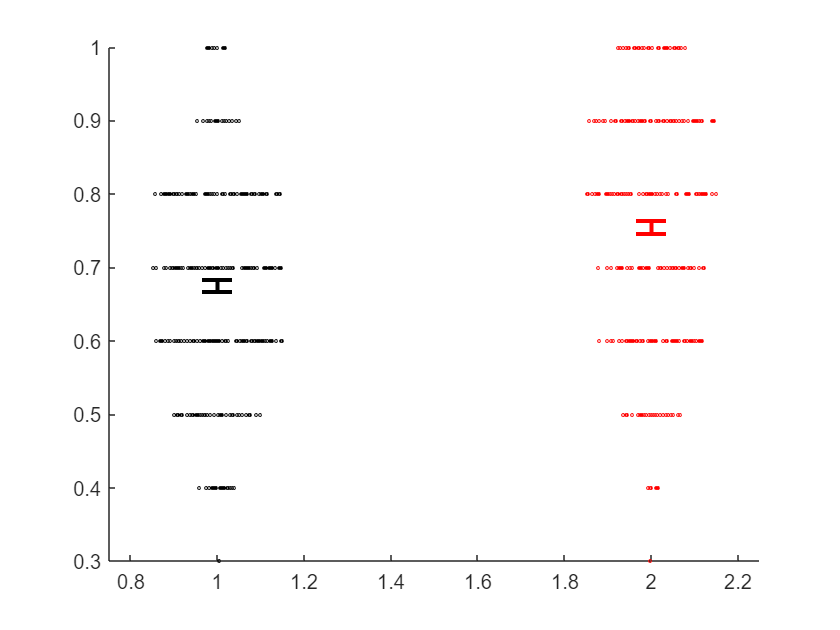

  lp = length(u_p1);
  figure
  hold on

  
  cg_lin = reshape(ClassDistLIN_N(1:lp,1:lp), 1, []);
  cg_lin = cg_lin(~isnan(cg_lin));
  st_lin = reshape(ClassDistLIN_N(lp+1:2*lp, lp+1:2*lp), 1, []);
  st_lin = st_lin(~isnan(st_lin));

clear s
 s{1} = swarmchart(ones(length(cg_lin),1), cg_lin , 2, 'k');
 
 s{2} = swarmchart(2*ones(length(st_lin),1), st_lin, 2,'r');
 
% s{3} = swarmchart(3*ones(length(cg_rbf),1), cg_rbf, 2, 'b') ;
% s{4} = swarmchart(4*ones(length(st_rbf),1), st_rbf, 2, 'r');
 
 for i = 1:2
     set(s{i}, 'XJitterWidth', .3);
 end
  box off
    lp = length(u_p1);
%  figure
%  hold on
% e1 = errorbar([1 3], [nanmean(cg_lin) nanmean(cg_rbf)], ...
%     [nanstd(cg_lin) nanstd(cg_rbf)]/sqrt(length(cg_lin)-1), 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 5);
% e1 = errorbar([2 4], [nanmean(st_lin) nanmean(st_rbf)], ...
%     [ nanstd(st_lin) nanstd(st_rbf)]/sqrt(length(cg_rbf)-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 5);

 e1 = errorbar(1, nanmean(cg_lin), ...
     nanstd(cg_lin)/sqrt(length(cg_lin)-1), 'LineStyle', 'none', 'Color', 'k', 'LineWidth', 2, 'CapSize', 15);
 e2 = errorbar(2, nanmean(st_lin), ...
     nanstd(st_lin)/sqrt(length(st_lin)-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 2, 'CapSize', 15 ...
     );
 


box off
  set(get(e1, 'parent'), 'XLim', [.75 2.25]);


  [a b] = ranksum(cg_lin, st_lin)

a = 3.6943e-10

b = logical
   1


  [a, b, n, stats] = ttest2(cg_lin, st_lin)

a = 1

b = 1.3689e-10

n =    -0.1025   -0.0551


stats = struct with fields:
    tstat: -6.5253
       df: 648
       sd: 0.1539


### Classification success for only dyads with SC-HIGH and SC-LOW animals 


%This code was moved to part 0 (Setup)
%
% sigdyads = find(ismember(rdb_rr.deguA, degutable(indsig,1)) | ismember(rdb_rr.deguB, degutable(indsig,1)));
% usig = unique(sigdyads);
% nonsigdyads = find(~ismember(1:length(rdb_rr.deguA), sigdyads));
% unsig = unique(nonsigdyads);
% 

%load ClassDistLIN_210715
ClassDistLIN(find(eye(length(ClassDistLIN)))) = nan;
for i = 1:5
    CDbyday(find(eye(length(ClassDistLIN))),i) = nan;
end
%ClassDistLIN = ClassDistLIN_N; % CHANGE THIS TO LOOK AT NORMALIZED VS. NON-NORMALIZED DATA


sigunsig = {sigdyads, nonsigdyads};
clear stt pts prs

cg_lin_sus = cell(2,1);
st_lin_sus = cell(2,1);

figure


for i = 1:2
    curind = intersect(indfemOneFive_f, sigunsig{i});
    curind_c = intersect(indfemOneFive_cag_f, sigunsig{i});
    curind_s = intersect(indfemOneFive_str_f, sigunsig{i});
    
    us_p1 = unique(labels_pair(curind_c));
    us_p2 = unique(labels_pair(curind_s));
    us_p = [us_p1 ; us_p2];

    sus_matind_cag = find(ismember(u_p1_f, us_p1));
    sus_matind_str = find(ismember(u_p2_f, us_p2))+lp_f;
    
 %   cg_rbf_sus = reshape(ClassDistRBF(sus_matind_cag, sus_matind_cag), 1, []);
 %   cg_rbf_sus = cg_rbf(~isnan(cg_rbf_sus));
 %   st_rbf_sus = reshape(ClassDistRBF(sus_matind_str, sus_matind_str), 1, []);
 %   st_rbf_sus = st_rbf(~isnan(st_rbf_sus));
  
    cg_lin_sus{i} = reshape(ClassDistLIN(sus_matind_cag,sus_matind_cag), 1, []);
    cg_lin_sus{i} = cg_lin_sus{i}(~isnan(cg_lin_sus{i}));
    st_lin_sus{i} = reshape(ClassDistLIN(sus_matind_str, sus_matind_str), 1, []);
    st_lin_sus{i} = st_lin_sus{i}(~isnan(st_lin_sus{i}));

  subplot(1,2,i);
  hold
clear s
 s{i,1} = swarmchart(ones(length(cg_lin_sus{i}),1), cg_lin_sus{i} , 2, 'CData', colorcodes_f(2,:));
 
 s{i,2} = swarmchart(2*ones(length(st_lin_sus{i}),1), st_lin_sus{i}, 2,'CData', colorcodes_f(1,:));
 
% s{3} = swarmchart(3*ones(length(cg_rbf_sus),1), cg_rbf_sus, 2, 'b') ;
% s{4} = swarmchart(4*ones(length(st_rbf_sus),1), st_rbf_sus, 2, 'r');
 
 for j = 1:2
     set(s{i,j}, 'XJitterWidth',.3);
 end
  box off
    lp = length(u_p1_f);
%  figure
%  hold on
%  e1 = errorbar([1 3], [nanmean(cg_lin_sus{i}) nanmean(cg_rbf_sus)], ...
%      [nanstd(cg_lin_sus{i}) nanstd(cg_rbf_sus)]/sqrt(length(cg_lin_sus{i})-1), 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 5);
%  e1 = errorbar([2 4], [nanmean(st_lin_sus{i}) nanmean(st_rbf_sus)], ...
%      [ nanstd(st_lin_sus{i}) nanstd(st_rbf_sus)]/sqrt(length(cg_rbf_sus)-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 5);
%  box off
 e1 = errorbar(1, [nanmean(cg_lin_sus{i})], ...
     [nanstd(cg_lin_sus{i})]/sqrt(length(cg_lin_sus{i})-1), 'LineStyle', 'none', 'Color', colorcodes_f(2,:), 'LineWidth', 2, 'CapSize', 15);
 e1 = errorbar(2, [nanmean(st_lin_sus{i})], ...
     [ nanstd(st_lin_sus{i})]/sqrt(length(st_lin_sus{i})-1), 'LineStyle', 'none', 'Color', colorcodes_f(1,:), 'LineWidth', 2, 'CapSize', 15);
 box off

  set(get(e1, 'parent'), 'XLim', [.75 2.25]);
    
  [prs(i), b] = ranksum(cg_lin_sus{i}, st_lin_sus{i});
  [a, pts(i), n, stt{i}] = ttest2(cg_lin_sus{i}, st_lin_sus{i});
    ylim(i,:) = get(get(s{i,1},'Parent'), 'YLim');
end

Current plot held
Current plot held


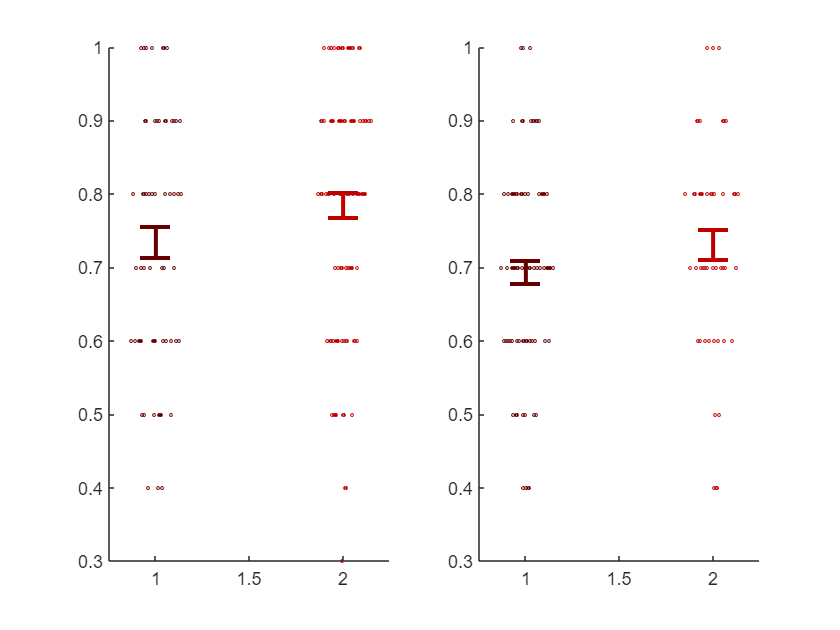

minylim = min(min(ylim));
maxylim = max(max(ylim));
for i = 1:2
    set(get(s{i,1}, 'Parent'), 'YLim', [minylim maxylim]);    
end

pts

pts =     0.0661    0.1425


stt{1}

ans = struct with fields:
    tstat: -1.8500
       df: 169
       sd: 0.1718


stt{2}

ans = struct with fields:
    tstat: -1.4745
       df: 144
       sd: 0.1489


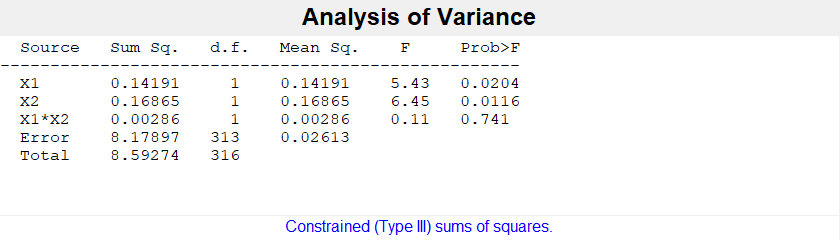


    anovacell{1} = [cg_lin_sus{1}' ; cg_lin_sus{2}' ; st_lin_sus{1}' ; st_lin_sus{2}'];
    anovacell{2} = [ones(length(cg_lin_sus{1}),1) ; ones(length(cg_lin_sus{2}),1) ; 2*ones(length(st_lin_sus{1}),1) ; 2*ones(length(st_lin_sus{2}),1)];
    anovacell{3} = [ones(length(cg_lin_sus{1}),1) ; 2*ones(length(cg_lin_sus{2}),1) ; ones(length(st_lin_sus{1}),1) ; 2*ones(length(st_lin_sus{2}),1)];
    
[P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');

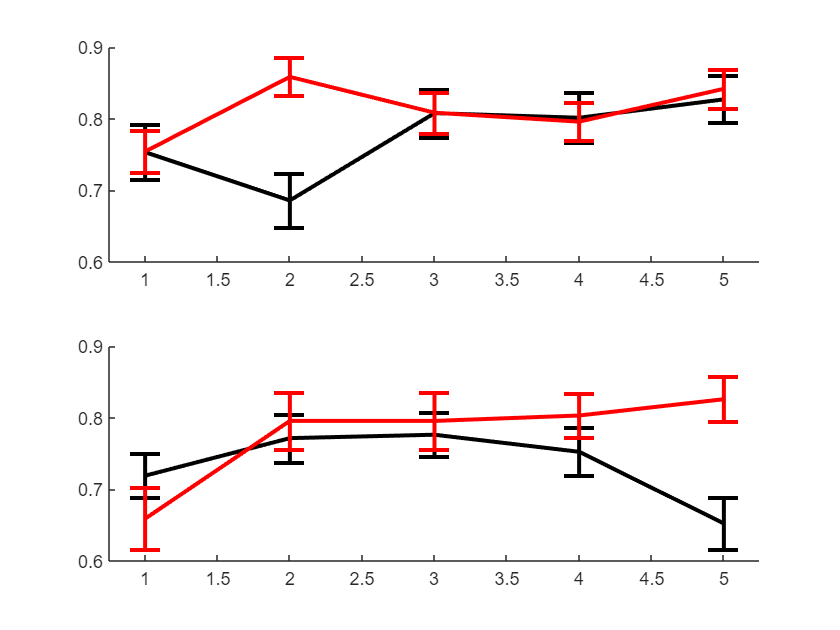

figure
for i = 1:2
    curind = intersect(indfemOneFive_f, sigunsig{i});
    curind_c = intersect(indfemOneFive_cag_f, sigunsig{i});
    curind_s = intersect(indfemOneFive_str_f, sigunsig{i});
    
    us_p1 = unique(labels_pair(curind_c));
    us_p2 = unique(labels_pair(curind_s));
    us_p = [us_p1 ; us_p2];

    sus_matind_cag = find(ismember(u_p1, us_p1));
    sus_matind_str = find(ismember(u_p2, us_p2))+lp;
    
 %   cg_rbf_sus = reshape(ClassDistRBF(sus_matind_cag, sus_matind_cag), 1, []);
 %   cg_rbf_sus = cg_rbf(~isnan(cg_rbf_sus));
 %   st_rbf_sus = reshape(ClassDistRBF(sus_matind_str, sus_matind_str), 1, []);
 %   st_rbf_sus = st_rbf(~isnan(st_rbf_sus));
  
 for j = 1:5
    cg_lin_susD{j} = reshape(CDbyday(sus_matind_cag,sus_matind_cag,j), 1, []);
    cg_lin_susD{j} = cg_lin_susD{j}(~isnan(cg_lin_susD{j}));
    st_lin_susD{j} = reshape(CDbyday(sus_matind_str, sus_matind_str,j), 1, []);
    st_lin_susD{j} = st_lin_susD{j}(~isnan(st_lin_susD{j}));

 
 % clear s

%  s{1} = swarmchart(ones(length(cg_lin),1), cg_lin , 2, 'b');
%  
%  s{2} = swarmchart(2*ones(length(st_lin),1), st_lin, 2,'r');
 
% s{3} = swarmchart(3*ones(length(cg_rbf),1), cg_rbf, 2, 'b') ;
% s{4} = swarmchart(4*ones(length(st_rbf),1), st_rbf, 2, 'r');
 
%  for j = 1:2
%      set(s{j}, 'XJitterWidth', .3);
%  end
 % box off
  %  lp = length(u_p1);
%  figure
%  hold on
%  e1 = errorbar([1 3], [nanmean(cg_lin) nanmean(cg_rbf)], ...
%      [nanstd(cg_lin) nanstd(cg_rbf)]/sqrt(length(cg_lin)-1), 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 2, 'CapSize', 15);
%  e1 = errorbar([2 4], [nanmean(st_lin) nanmean(st_rbf)], ...
%      [ nanstd(st_lin) nanstd(st_rbf)]/sqrt(length(cg_rbf)-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 2, 'CapSize', 15);

   % [a(i), b(i), s] = ranksum(cg_lin_susD{i}, st_lin_susD{i})
 end
 subplot(2,1,i)
 hold on
  e1 = errorbar([1:5], [nanmean(cg_lin_susD{1}) nanmean(cg_lin_susD{2}) nanmean(cg_lin_susD{3}) nanmean(cg_lin_susD{4}) nanmean(cg_lin_susD{5})], ...
     [nanstd(cg_lin_susD{1}) nanstd(cg_lin_susD{2}) nanstd(cg_lin_susD{3}) nanstd(cg_lin_susD{4}) nanstd(cg_lin_susD{5})]./...
     [sqrt(length(cg_lin_susD{1})-1) sqrt(length(cg_lin_susD{2})-1) sqrt(length(cg_lin_susD{3})-1) sqrt(length(cg_lin_susD{4})-1) sqrt(length(cg_lin_susD{5})-1)], 'Color', 'k', 'LineWidth', 2, 'CapSize', 15);
   
      e1 = errorbar(1:5, [nanmean(st_lin_susD{1}) nanmean(st_lin_susD{2}) nanmean(st_lin_susD{3}) nanmean(st_lin_susD{4}) nanmean(st_lin_susD{5})], ...
     [nanstd(st_lin_susD{1}) nanstd(st_lin_susD{2}) nanstd(st_lin_susD{3}) nanstd(st_lin_susD{4}) nanstd(st_lin_susD{5})]./...
     [sqrt(length(st_lin_susD{1})-1) sqrt(length(st_lin_susD{2})-1) sqrt(length(st_lin_susD{3})-1) sqrt(length(st_lin_susD{4})-1) sqrt(length(st_lin_susD{5})-1)], 'Color', 'r', 'LineWidth', 2, 'CapSize', 15);

 box off
  set(get(e1, 'parent'), 'XLim', [.75 5.25]); 
end

### Repeat SVM after removing individual interaction types


%   
% ClassDistRBF = IVclass_sess(sbID, indfemOneFive, u_p, rdb_rr.paircode, labels_pair, 'rbf'); 
%ClassDistLIN = IVclass_sess(sbID, indfemOneFive, u_p, rdb_rr.paircode, labels_pair, 'linear');
% 
% ClassDistLin_red_m = cell(5,1);
%  tic
%    for k = 1:5
%      switch k
%          case 1
%              newsumbehav = sumbehavID2(:, [2:4 6:end]).^(1/3);
%          case 2
%              newsumbehav = sumbehavID2(:, [1 2:5 7:end]).^(1/3);
%          case 3
%              newsumbehav = sumbehavID2(:, [1 2:5 7:end]).^(1/3);
%          case 4
%              newsumbehav = sumbehavID2(:,1:8).^(1/3);
%          case 5
%              newsumbehav = sumbehavID2(:, [1:3 5:7 9]).^(1/3);
%      end
% %     [ClassDistLIN, CDbyday] = IVclass_sess2(sbID, indmalOneFive_m, u_p_m, labels_pair, 'linear', exp_pair);
%     % ClassDistRBF = IVclass_sess(sbID, indfemOneFive, u_p, rdb_rr.paircode, labels_pair, 'rbf'); 
%     fprintf('%d', k);
%      toc
%      tic
%      estr = 'ClassDistLIN_red_m{k} = IVclass_sess(newsumbehav, indmalOneFive_m, u_p_m, labels_pair, ''linear'');';
%      evalc(estr); %using evalc to remove the prints to screen (I think)
%    end
%    save ClassDistLin_red_m ClassDistLIN_red_m

    load ClassDistLin_red
    load ClassDistLin_red_m

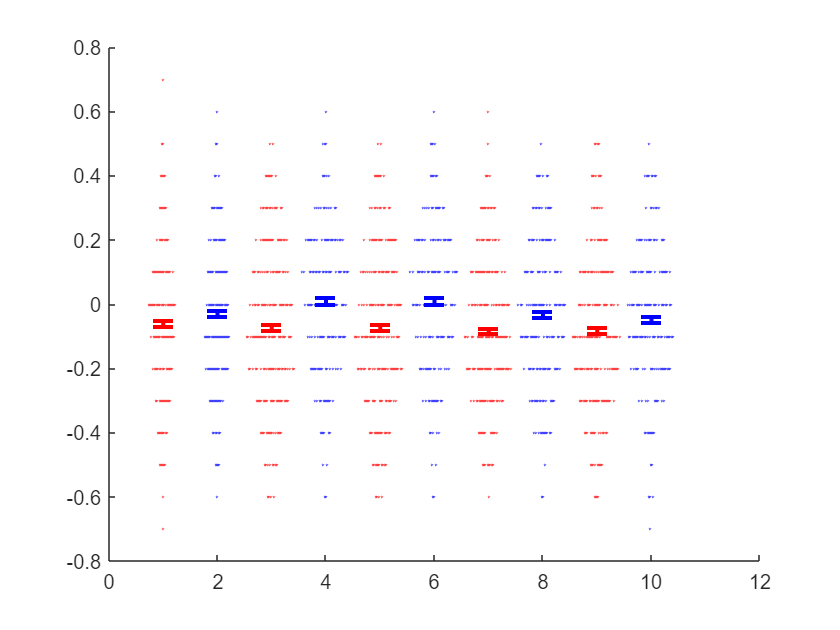


    figure
hold on
    for i = 1:5
        ClassDistLIN_red{i}(find(eye(length(ClassDistLIN_red{i})))) = nan;
        cg_lin_red{i} = reshape(ClassDistLIN_red{i}(1:lp_f,1:lp_f), 1, []);
        cg_lin_red{i} = cg_lin_red{i}(~isnan(cg_lin_red{i}));
        st_lin_red{i} = reshape(ClassDistLIN_red{i}(lp_f+1:2*lp_f, lp_f+1:2*lp_f), 1, []);
        st_lin_red{i} = st_lin_red{i}(~isnan(st_lin_red{i}));
        cgMst_lin_red{i} = reshape(ClassDistLIN_red{i}(1:lp_f,1:lp_f) - ClassDistLIN_red{i}(lp_f+1:2*lp_f, lp_f+1:2*lp_f), [],1);

        ClassDistLIN_red_m{i}(find(eye(length(ClassDistLIN_red_m{i})))) = nan;
        cg_lin_red_m{i} = reshape(ClassDistLIN_red_m{i}(1:lp_m,1:lp_m), 1, []);
        cg_lin_red_m{i} = cg_lin_red_m{i}(~isnan(cg_lin_red_m{i}));
        st_lin_red_m{i} = reshape(ClassDistLIN_red_m{i}(lp_m+1:2*lp_m, lp_m+1:2*lp_m), 1, []);
        st_lin_red_m{i} = st_lin_red_m{i}(~isnan(st_lin_red{i}));
        cgMst_lin_red_m{i} = reshape(ClassDistLIN_red_m{i}(1:lp_m,1:lp_m) - ClassDistLIN_red{i}(lp_m+1:2*lp_m, lp_m+1:2*lp_m), [],1);



%clear sred

 sred{((i-1)*2)+1} = swarmchart(((i-1)*2)+ones(length(cgMst_lin_red{i}),1), cgMst_lin_red{i} , 1, 'r', 'LineWidth', 0.2);
 
 sred{((i-1)*2)+2} = swarmchart(((i-1)*2)+2*ones(length(cgMst_lin_red_m{i}),1), cgMst_lin_red_m{i}, 1,'b', 'LineWidth', 0.2);
 
%  s{3} = swarmchart(3*ones(length(cg_rbf),1), cg_rbf, 2, 'b') ;
%  s{4} = swarmchart(4*ones(length(st_rbf),1), st_rbf, 2, 'r');
 
 for j = 1:2
     set(sred{j}, 'XJitterWidth', .5);
 end
  box off
    %lp = length(u_p1);
    
%  figure
%  hold on
 e1 = errorbar(((i-1)*2)+1, nanmean(cgMst_lin_red{i}), ...
     nanstd(cgMst_lin_red{i})/sqrt(length(cgMst_lin_red{i})-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 2, 'CapSize', 10);
 e1 = errorbar(((i-1)*2)+2, nanmean(cgMst_lin_red_m{i}), ...
     nanstd(cgMst_lin_red_m{i})/sqrt(length(cgMst_lin_red_m{i})-1), 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 2, 'CapSize', 10);
 box off

%   [a, p_red(i), n, stat_red{i}] = ttest2(cg_lin_red{i}, st_lin_red{i});
    end

%Alternate figure for supplementary 

  h =  figure

h =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


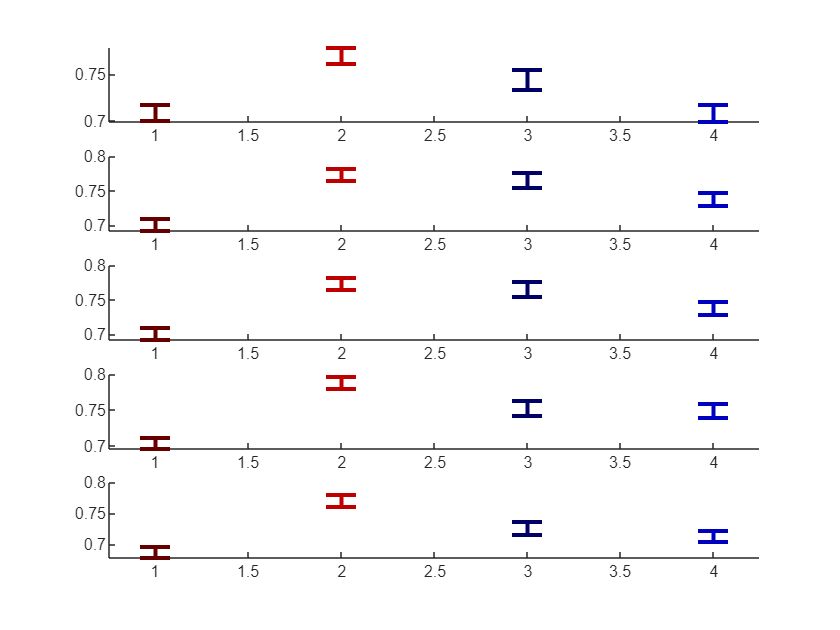


    for i = 1:5
        ClassDistLIN_red{i}(find(eye(length(ClassDistLIN_red{i})))) = nan;
        cg_lin_red{i} = reshape(ClassDistLIN_red{i}(1:lp_f,1:lp_f), 1, []);
        cg_lin_red{i} = cg_lin_red{i}(~isnan(cg_lin_red{i}));
        st_lin_red{i} = reshape(ClassDistLIN_red{i}(lp_f+1:2*lp_f, lp_f+1:2*lp_f), 1, []);
        st_lin_red{i} = st_lin_red{i}(~isnan(st_lin_red{i}));
        cgMst_lin_red{i} = reshape(ClassDistLIN_red{i}(1:lp_f,1:lp_f) - ClassDistLIN_red{i}(lp_f+1:2*lp_f, lp_f+1:2*lp_f), [],1);

        ClassDistLIN_red_m{i}(find(eye(length(ClassDistLIN_red_m{i})))) = nan;
        cg_lin_red_m{i} = reshape(ClassDistLIN_red_m{i}(1:lp_m,1:lp_m), 1, []);
        cg_lin_red_m{i} = cg_lin_red_m{i}(~isnan(cg_lin_red_m{i}));
        st_lin_red_m{i} = reshape(ClassDistLIN_red_m{i}(lp_m+1:2*lp_m, lp_m+1:2*lp_m), 1, []);
        st_lin_red_m{i} = st_lin_red_m{i}(~isnan(st_lin_red{i}));
        cgMst_lin_red_m{i} = reshape(ClassDistLIN_red_m{i}(1:lp_m,1:lp_m) - ClassDistLIN_red{i}(lp_m+1:2*lp_m, lp_m+1:2*lp_m), [],1);
% 

  
  
    subplot(5,1,i)
    hold on
clear s
%  s{1} = swarmchart(ones(length(cg_lin_red{i}),1), cg_lin_red{i} , .75, 'MarkerEdgeColor', colorcodes_f(2,:));
%  s{2} = swarmchart(2*ones(length(st_lin_red_m{i}),1), st_lin_red{i}, .75, 'MarkerEdgeColor', colorcodes_f(1,:));

%  s{3} = swarmchart(3*ones(length(cg_lin_red_m{i}),1), cg_lin_red_m{i} , .75, 'MarkerEdgeColor', colorcodes_m(2,:));
%  s{4} = swarmchart(4*ones(length(st_lin_red_m{i}),1), st_lin_red_m{i}, .75, 'MarkerEdgeColor', colorcodes_m(1,:));
  
  
%  s{3} = swarmchart(3*ones(length(cg_rbf),1), cg_rbf, 2, 'b') ;
%  s{4} = swarmchart(4*ones(length(st_rbf),1), st_rbf, 2, 'r');
 
% for k = 1:4
%     set(s{k}, 'XJitterWidth', .3);
% end
  box off
    lp_f = length(u_p1_f);
    lp_m = length(u_p1_m);

    %  figure
%  hold on
%  e1 = errorbar([1 3], [nanmean(cg_lin) nanmean(cg_rbf)], ...
%      [nanstd(cg_lin) nanstd(cg_rbf)]/sqrt(length(cg_lin)-1), 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 2, 'CapSize', 15);
%  e1 = errorbar([2 4], [nanmean(st_lin) nanmean(st_rbf)], ...
%      [ nanstd(st_lin) nanstd(st_rbf)]/sqrt(length(cg_rbf)-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 2, 'CapSize', 15);
 e1 = errorbar(1, nanmean(cg_lin_red{i}), ...
     nanstd(cg_lin_red{i})/sqrt(length(cg_lin_red{i})-1), 'LineStyle', 'none', 'Color', colorcodes_f(2,:), 'LineWidth', 2, 'CapSize', 15);
 e1 = errorbar(2, nanmean(st_lin_red{i}), ...
     nanstd(st_lin_red{i})/sqrt(length(st_lin_red{i})-1), 'LineStyle', 'none', 'Color', colorcodes_f(1,:), 'LineWidth', 2, 'CapSize', 15);

 e1 = errorbar(3, nanmean(cg_lin_red_m{i}), ...
     nanstd(cg_lin_red_m{i})/sqrt(length(cg_lin_red_m{i})-1), 'LineStyle', 'none', 'Color', colorcodes_m(2,:), 'LineWidth', 2, 'CapSize', 15);
 e1 = errorbar(4, nanmean(st_lin_red_m{i}), ...
     nanstd(st_lin_red_m{i})/sqrt(length(st_lin_red_m{i})-1), 'LineStyle', 'none', 'Color', colorcodes_m(1,:), 'LineWidth', 2, 'CapSize', 15);


 box off
  set(get(e1, 'parent'), 'XLim', [.75 4.25]); 
    end

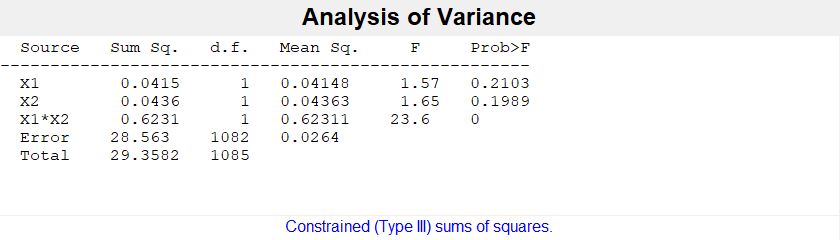

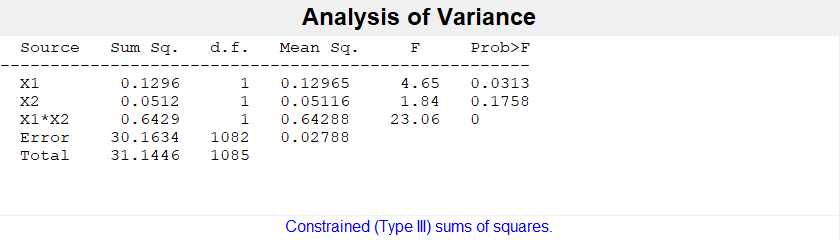

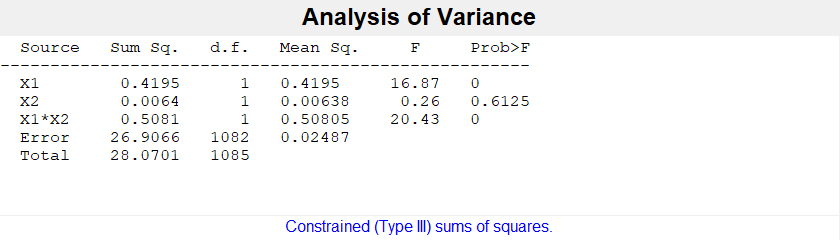

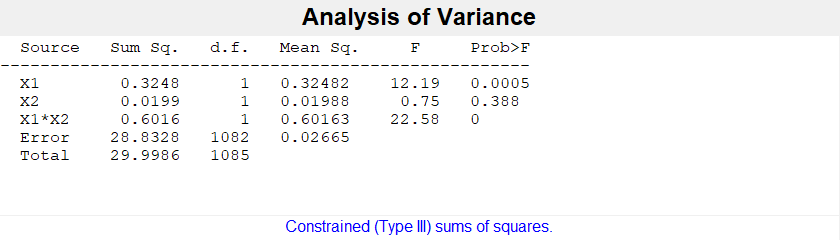

clear P
for i = 1:5
    anovacell = cell(3,1);
    anovacell{1} = [cg_lin_red{i}' ; st_lin_red{i}' ; cg_lin_red_m{i}' ; st_lin_red_m{i}'];
    anovacell{2} = [ones(length(cg_lin_red{i}),1) ; 2*ones(length(st_lin_red{i}),1) ; ones(length(cg_lin_red_m{i}),1) ; 2*ones(length(st_lin_red_m{i}),1)];
    anovacell{3} = [ones(length(cg_lin_red{i}),1) ; ones(length(st_lin_red{i}),1) ; 2*ones(length(cg_lin_red_m{i}),1) ; 2*ones(length(st_lin_red_m{i}),1)];

    [P{i},T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');

    [~, pt_f(i)] = ttest(cgMst_lin_red{i});
    [~, pt_m(i)] = ttest(cgMst_lin_red_m{i});
end

pt_f

pt_f = 1.0e-05 *

    0.1435    0.0230    0.0230    0.0000    0.0001


pt_m

pt_m =     0.0380    0.5132    0.5132    0.0252    0.0017


    
%     
%     p_red
%  anovacell{1} = [cg_lin_red{1}' ; cg_lin_red{2}' ; cg_lin_red{3}'; cg_lin_red{4}'; cg_lin_red{5}'; ...
%      st_lin_red{1}' ; st_lin_red{2}' ; st_lin_red{3}' ; st_lin_red{4}' ;st_lin_red{5}'];
%  anovacell{2} = [ones(length(cg_lin_red{1}),1) ; ones(length(cg_lin_red{2}),1) ; ones(length(cg_lin_red{3}),1) ; ones(length(cg_lin_red{4}),1) ; ones(length(cg_lin_red{5}),1); ...
%      2*ones(length(st_lin_red{1}),1) ; 2*ones(length(st_lin_red{2}),1) ; 2*ones(length(st_lin_red{3}),1) ; 2*ones(length(st_lin_red{4}),1) ; 2*ones(length(st_lin_red{5}),1)];
%  anovacell{3} = [ones(length(cg_lin_red{1}),1) ; 2*ones(length(cg_lin_red{2}),1) ; 3*ones(length(cg_lin_red{3}),1) ; 4*ones(length(cg_lin_red{4}),1) ; 5*ones(length(cg_lin_red{5}),1) ;...
%      ones(length(st_lin_red{1}),1) ; 2*ones(length(st_lin_red{2}),1) ; 3*ones(length(st_lin_red{3}),1) ; 4*ones(length(st_lin_red{4}),1) ; 5*ones(length(st_lin_red{5}),1)];
%     
% [P,T,STATS,TERMS]=anovan(anovacell{1},anovacell(2:3), 'model', 'interaction');

### Dyad Classification in Scrambled Control (Label Scramble)

Works but currently not using for simplicity

% 
% sbID = sumbehavID2.^(1/3);
%  
% ClassDistLIN_scram = cell(5,1); 
% for k = 1:5 
%     labels_pairs_scram = labels_pair;
%     labels_pairs_scram(indfemOneFive_f) = labels_pair(indfemOneFive_f(randperm(length(indfemOneFive_f))));
%     
%     fprintf('%d', k);
%     estr = 'ClassDistLIN_scram{k} = IVclass_sess(sbID, indfemOneFive, u_p, labels_pairs_scram, ''linear'');';
%     evalc(estr);
%     
% end

% for i = 1:5
%   ClassDistLIN_scram{i}(find(eye(length(ClassDistLIN_scram{i})))) = nan;
%   cg_lin_scm{i} = reshape(ClassDistLIN_scram{i}(1:lp,1:lp), 1, []);
%   cg_lin_scm{i} = cg_lin_scm{i}(~isnan(cg_lin_scm{i}));
%   st_lin_scm{i} = reshape(ClassDistLIN_scram{i}(lp+1:2*lp, lp+1:2*lp), 1, []);
%   st_lin_scm{i} = st_lin_scm{i}(~isnan(st_lin_scm{i}));
%   
% 
% clear sred
% figure
% hold on
%  sscm{1} = swarmchart(ones(length(cg_lin_scm{i}),1), cg_lin_scm{i} , 2, 'b');
%  
%  sscm{2} = swarmchart(2*ones(length(st_lin_scm{i}),1), st_lin_scm{i}, 2,'r');
%  
% %  s{3} = swarmchart(3*ones(length(cg_rbf),1), cg_rbf, 2, 'b') ;
% %  s{4} = swarmchart(4*ones(length(st_rbf),1), st_rbf, 2, 'r');
%  
%  for j = 1:2
%      set(sscm{j}, 'XJitterWidth', .3);
%  end
%   box off
%     lp = length(u_p1);
% %  figure
% %  hold on
%  e1 = errorbar(1, nanmean(cg_lin_scm{i}), ...
%      nanstd(cg_lin_scm{i})/sqrt(length(cg_lin_scm{i})-1), 'LineStyle', 'none', 'Color', 'b', 'LineWidth', 5);
%  e1 = errorbar(2, nanmean(st_lin_scm{i}), ...
%      nanstd(st_lin_scm{i})/sqrt(length(cg_lin_scm{i})-1), 'LineStyle', 'none', 'Color', 'r', 'LineWidth', 5);
%  box off
% 
%    [a, p_scm(i), n, stat_scm{i}] = ttest2(cg_lin_scm{i}, st_lin_scm{i})
% end